#                                                     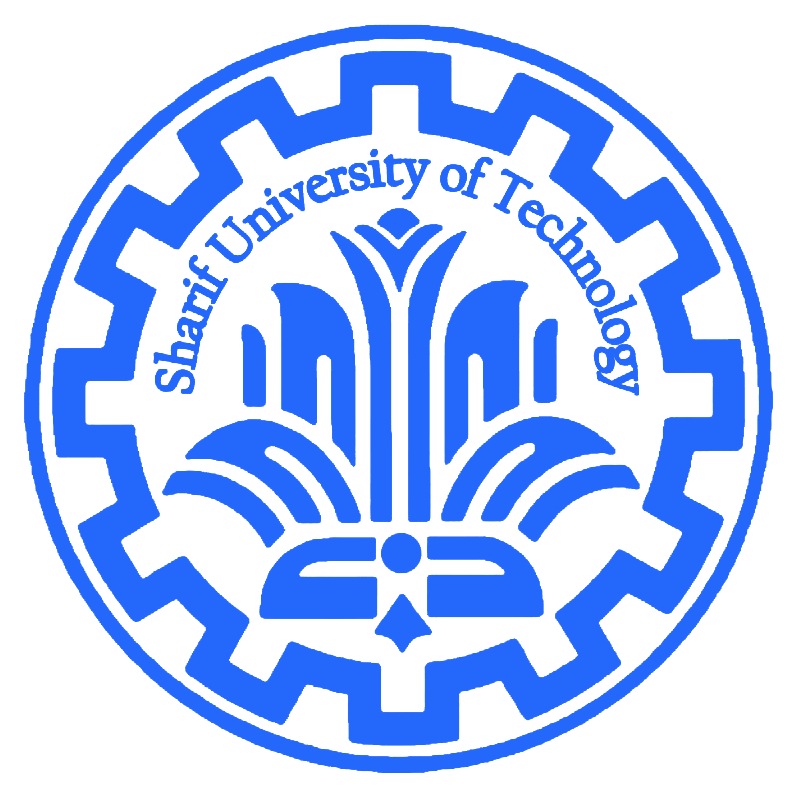        

# 
$$\textbf{Stochastic Processes}
$$


# 
$$\text{Computer Assignment \#2
}
$$


#### 
$$\textit{Masoud Tahmasbi Fard - 402200275
}$$


### 
$$\textbf{Question \#1}$$


**............................................................................................................**

### 
$$\text{Part A}.$$
 

.............................................................................................................

N = 100;
N_simulation = 1e6;
final_positions1 = zeros(N_simulation,1);

for i_simulation = 1:N_simulation
    r = rand(N,1);
    theta = 2*pi*rand(N,1);
    final_positions1(i_simulation) = sum(r.*exp(1i.*theta));
end

fprintf('N = %4.1f, Varinace of movement: %4.4f, Mean value of movement: %4.4f + j(%4.4f)\n',N,var(final_positions1),real(mean(final_positions1)),imag(mean(final_positions1)))

N = 100.0, Varinace of movement: 33.3212, Mean value of movement: -0.0024 + j(-0.0069)


N = 1000;
N_simulation = 1e6; 
final_positions2 = zeros(N_simulation,1);

for i_simulation = 1:N_simulation
    r = rand(N,1);
    theta = 2*pi*rand(N,1);
    final_positions2(i_simulation) = sum(r.*exp(1i.*theta));
end

fprintf('N = %4.1f, Varinace of movement: %4.4f, Mean value of movement: %4.4f + j(%4.4f)\n',N,var(final_positions2),real(mean(final_positions2)),imag(mean(final_positions2)))

N = 1000.0, Varinace of movement: 333.5034, Mean value of movement: 0.0141 + j(-0.0071)


N = 10000;
N_simulation = 1e6;
final_positions3 = zeros(N_simulation,1);

tic
for i_simulation = 1:N_simulation
    r = rand(N,1);
    theta = 2*pi*rand(N,1);
    final_positions3(i_simulation) = sum(r.*exp(1i.*theta));
end

fprintf('N = %4.1f, Varinace of movement: %4.4f, Mean value of movement: %4.4f + j(%4.4f)\n',N,var(final_positions3),real(mean(final_positions3)),imag(mean(final_positions3)))

N = 10000.0, Varinace of movement: 3326.3555, Mean value of movement: 0.0518 + j(-0.0077)


### 
$$\text{Part B}.$$
 

.............................................................................................................

N = 100;
N_simulation = 1e6;
cnt = 0;

for i_simulation = 1:N_simulation
    r = rand(N,1);
    theta = 2*pi*rand(N,1);
    position = sum(r.*exp(1i.*theta));

    if (8 < abs(position) && abs(position) < 12)
        cnt = cnt + 1;
    end
end
fprintf('N = %4.1f, Probability of end point falling inside the disk: %4.4f\n',N,cnt/N_simulation)

N = 100.0, Probability of end point falling inside the disk: 0.1334


N = 1000;
N_simulation = 1e6;
cnt = 0;

for i_simulation = 1:N_simulation
    r = rand(N,1);
    theta = 2*pi*rand(N,1);
    position = sum(r.*exp(1i.*theta));

    if (8 < abs(position) && abs(position) < 12)
        cnt = cnt + 1;
    end
end
fprintf('N = %4.1f, Probability of end point falling inside the disk: %4.4f\n',N,cnt/N_simulation)

N = 1000.0, Probability of end point falling inside the disk: 0.1754


N = 10000;
N_simulation = 1e6;
cnt = 0;

for i_simulation = 1:N_simulation
    r = rand(N,1);
    theta = 2*pi*rand(N,1);
    position = sum(r.*exp(1i.*theta));

    if (8 < abs(position) && abs(position) < 12)
        cnt = cnt + 1;
    end
end
fprintf('N = %4.1f, Probability of end point falling inside the disk: %4.4f\n',N,cnt/N_simulation)

N = 10000.0, Probability of end point falling inside the disk: 0.0236


### 
$$\text{Part C}.$$
 

.............................................................................................................

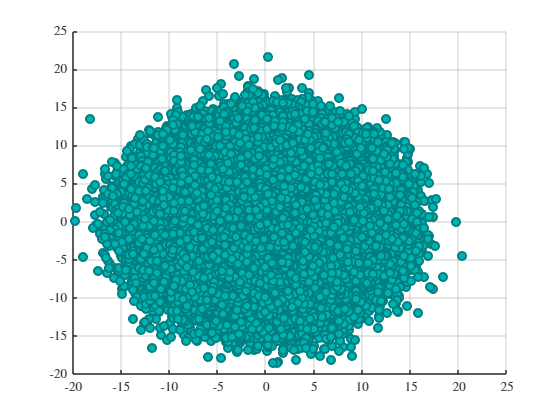

scatter(real(final_positions1),imag(final_positions1),'MarkerEdgeColor' ,[0 .5 .5], ... 
              'MarkerFaceColor' ,[0 .7 .7], ... 
              'LineWidth' ,1.5)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
grid on;

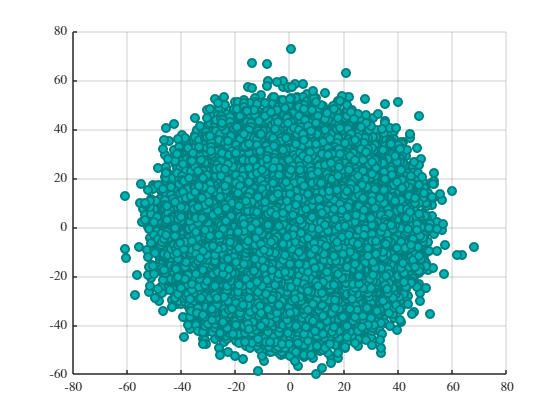

scatter(real(final_positions2),imag(final_positions2),'MarkerEdgeColor' ,[0 .5 .5], ... 
              'MarkerFaceColor' ,[0 .7 .7], ... 
              'LineWidth' ,1.5)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
grid on;

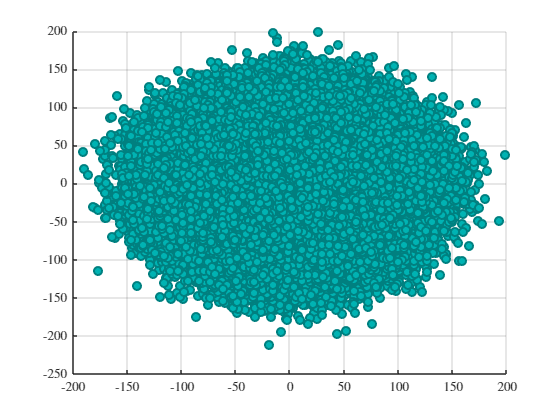

scatter(real(final_positions3),imag(final_positions3),'MarkerEdgeColor' ,[0 .5 .5], ... 
              'MarkerFaceColor' ,[0 .7 .7], ... 
              'LineWidth' ,1.5)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
grid on;

### 
$$\textbf{Appendix}. \\
\text{Emperical proof of CLT}$$
 

.............................................................................................................

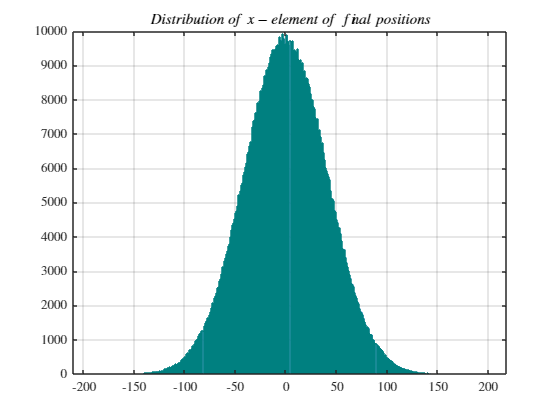

figure
histogram(real(final_positions3),'EdgeColor','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$Distribution\;of\;x-element\;of\;final\;positions$','interpreter','latex')
grid on;

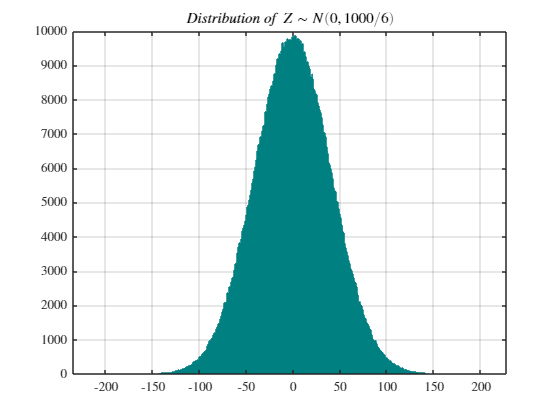

figure
histogram(randn(N_simulation,1)*sqrt(10000/6),'EdgeColor','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$Distribution\;of\;Z \sim N(0,1000/6)$','interpreter','latex')
grid on;